% (C) Copyright 2020 Murilo Marques Marinho
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho - murilo@nml.t.u-tokyo.ac.jp
clear all;
close all;

# Quaternion Basics using DQ Robotics

## Introduction

Before going into the topic of quaternions, it is important to review some high-school level math.

## Quick review on complex numbers

The set of complex numbers $\mathbb{C}$,  can be understood as an extention of the set of real numbers $\mathbb{R}$. Any complex number can always be written in the form


$$\mathit{\mathbf{c}}=a+b\hat{\;\i \;,}$$


where $a,b\in \;$$\mathbb{R}$. In addition, the imaginary unit, $\hat{\;\i \;}$ has the following property


$${\hat{\;\i \;} }^2 =-1\ldotp$$


For instance, the complex number


$${\mathit{\mathbf{c}}}_1 =5+28\hat{\i \;} \;$$


can be written using DQ Robotics as follows.

%% Include the namespace. Probably a good idea to add to all scripts.
include_namespace_dq

%% Define c1
c1 = 5 + 28*i_

c1 = 
         5 + 28i


Notice that the imaginary unit property holds:

%% Imaginary unit property
i_*i_

ans = 
          - 1


***Note: Do not confuse MATLAB's "i" with DQ Robotics "i_". They are different***

if i_ ~= i
    disp('DQ Robotics i_ is not equal to MATLAB i')
end

DQ Robotics i_ is not equal to MATLAB i


### **Operations on complex numbers**

The operations on complex numbers are very similar to the operations on real numbers. We just need to respect the property ${\hat{\;\i \;} }^2 =-1\ldotp$

For instance, for the complex numbers


$$c_1 =a_1 +b_1 \hat{\i \;}$$


$c_2 =a_2 +b_2 \hat{\i \;}$, 

c1 = 5  + 28*i_

c1 = 
         5 + 28i


c2 = 25 + 88*i_

c2 = 
         25 + 88i


#### Sum/Subtraction


$$c_3 =c_1 +c_2 =\left(a_1 +a_2 \right)+\left(b_1 +b_2 \right)\hat{\;\i \;} \ldotp$$


c3 = c1+c2

c3 = 
         30 + 116i


The subtraction is defined accordingly.


$${\;c}_1 -c_2 =\left(a_1 -a_2 \right)+\left(b_1 -b_2 \right)\hat{\;\i \;} \ldotp$$


c1-c2

ans = 
          - 20 - 60i


#### Product

The product will be


$${\;c}_1 c_2 =\left(a_1 a_2 -b_1 b_2 \right)+\left(a_1 b_1 +a_2 b_2 \right)\hat{\;\i \;}$$


c1*c2

ans = 
          - 2339 + 1140i


#### **Conjugation**

The conjugate of a complex number is defined as


$${\left(c_1 \right)}^* =a-b\hat{\;\i \;}$$


conj(c1)

ans = 
         5 - 28i


#### Norm

The norm of a complex number can be obtained as


$$\left|\right|c_1 \left|\right|=\sqrt{c_1 c_1^* \;}=\sqrt{\left(a_1 +b_1 \hat{\i \;} \right)\left(a_1 -b_1 \hat{\i \;} \right)\;}=\sqrt{a_1^2 +b_1^2 }$$


norm(c1)

ans = 
         28.4429


#### **Imaginary part**

The imaginary part is


$$\textrm{Im}\left(c_1 \right)=b\hat{\;\i \;}$$


Im(c1)

ans = 
         28i


#### Real

The real part is


$$\textrm{Re}\left(c_1 \right)=a$$


Re(c1)

ans = 
         5


## **Quaternions**

When we extend the concept of complex numbers to four dimensions, we have what we call quaternions. They compose the set $\mathbb{H}$ and can always be written in the form 


$$\mathit{\mathbf{h}}=a+b\hat{\;\i \;} +c\hat{\;\j \;} +d\hat{\;k}$$


where $a,b,c,d\in \;$$\mathbb{R}$. In addition, the imaginary units $\hat{\;\i \;}$, $\hat{\;\j \;}$, and $\hat{\;k\;}$ have the following properties


$${\hat{\;\i \;} }^2 ={\hat{\;\j \;} }^2 ={\hat{\;k} }^2 =\hat{\;\i \;} \hat{\;\j \;} \hat{\;k} =-1$$


Note that every complex number is a quaternion, but not every quaternion is a complex number ($\mathbb{C} \subset \mathbb{H} $).

For instance, the quaternion


$${\mathit{\mathbf{c}}}_1 =5+28\hat{\i \;} +85\hat{\;\j \;} +99\hat{\;k}$$


can be written using DQ Robotics as follows

%% Include the namespace. Probably a good idea to add to all scripts.
include_namespace_dq

%% Define c1
c1 = 5 + 28*i_ + 86*j_ + 99*k_

c1 = 
         5 + 28i + 86j + 99k


We can verify the properties of the imaginary units in DQ Robotics as follows

i_^2

ans = 
          - 1


j_^2

ans = 
          - 1


k_^2

ans = 
          - 1


i_*j_*k_

ans = 
          - 1


***Note: Do not confuse MATLAB's "i" and "j" with DQ Robotics "i_" and "j_". They are not equal.***

if i_ ~= i
    disp('DQ Robotics i_ is not equal to MATLAB i')
end

DQ Robotics i_ is not equal to MATLAB i


if j_ ~= j
    disp('DQ Robotics j_ is not equal to MATLAB j')
end

DQ Robotics j_ is not equal to MATLAB j


### Operations on quaternions

Considering ${\mathit{\mathbf{h}}}_1 ,{\mathit{\mathbf{h}}}_2 \in \;$$\mathbb{H}$, for example

h1 = 5 + 28*i_ + 86*j_ + 99*k_

h1 = 
         5 + 28i + 86j + 99k


h2 = -2 + 25*k_

h2 = 
          - 2 + 25k


#### Sum/Subtraction


$${\mathit{\mathbf{h}}}_1 \pm {\mathit{\mathbf{h}}}_2 =\left(a_1 \pm a_2 \right)+\left(b_1 \pm b_2 \right)\hat{\;\i \;} +\left(c_1 \pm c_2 \right)\hat{\;\j \;} +\left(d_1 \pm d_2 \right)\hat{\;k\;}$$


h1+h2

ans = 
         3 + 28i + 86j + 124k


h1-h2

ans = 
         7 + 28i + 86j + 74k


#### **Multiplication**


$${\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2 =\textrm{See}\;\textrm{Bonus}\;\textrm{Homework}\;1\ldotp$$


h1*h2

ans = 
          - 2485 + 2094i - 872j - 73k


Notice that the multiplication between quaternions is, ***in general***, NOT COMMUTATIVE.


$${\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2 \not= {{\mathit{\mathbf{h}}}_2 \mathit{\mathbf{h}}}_1$$


h3 = h1*h2 

h3 = 
          - 2485 + 2094i - 872j - 73k


h4 = h2*h1

h4 = 
          - 2485 - 2206i + 528j - 73k


if h3==h4
    disp('h1*h2 is equal to h2*h1')
else 
    disp('h1*h2 is not equal to h2*h1')
end

h1*h2 is not equal to h2*h1


It can be communitative in some cases. For instance, consider the trivial case in which $h_1 =h_2$.

#### Conjugation


$${\left(\mathit{\mathbf{h}}\right)}^* =a-b\hat{\;\i \;} -c\hat{\;\j \;} -d\hat{\;k}$$


conj(h1)

ans = 
         5 - 28i - 86j - 99k


**Norm**


$$\left|\right|{\mathit{\mathbf{h}}}_1 \left|\right|=\sqrt{{\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_1^* \;}=\textrm{See}\;\textrm{Bonus}\;\textrm{Homework}\;2\ldotp$$


norm(h1)

ans = 
         134.1864


#### Real part


$$\textrm{Re}\left({\mathit{\mathbf{h}}}_1 \right)=a$$


Re(h1)

ans = 
         5


If the real part of a quaternion is zero, it is called a *pure quaternion*, and belongs to the set $\mathbb{H}_p$

#### Imaginary part


$$\textrm{Im}\left({\mathit{\mathbf{h}}}_1 \right)=b\hat{\;\i \;} +c\hat{\;\j \;} +d\hat{\;k}$$


Im(h1)

ans = 
         28i + 86j + 99k


#### Vec3

Quaternions can be mapped to $\mathbb{R}^3$ as follows


$${\textrm{vec}}_3 \left({\mathit{\mathbf{h}}}_1 \right)=\left\lbrack \begin{array}{c}
b\\
c\\
d
\end{array}\right\rbrack$$


vec3(h1)

ans =     28
    86
    99


#### Vec4

Quaternions can be mapped to $\mathbb{R}^4$ as follows


$${\textrm{vec}}_4 \left({\mathit{\mathbf{h}}}_1 \right)=\left\lbrack \begin{array}{c}
a\\
b\\
c\\
d
\end{array}\right\rbrack$$


vec4(h1)

ans =      5
    28
    86
    99


#### Hamilton Operators

The hamilton operators are useful to provide a form of commutativity in the quaternion multiplication.


$$\textrm{vec}\left({\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2 \right)=\overset{+}{{\mathit{\mathbf{H}}}_4 } \left({\mathit{\mathbf{h}}}_1 \right)\textrm{vec}\left({\mathit{\mathbf{h}}}_1 \right)=\overset{-}{{\mathit{\mathbf{H}}}_4 } \left({\mathit{\mathbf{h}}}_2 \right)\textrm{vec}\left({\mathit{\mathbf{h}}}_1 \right)$$


vec4(h1*h2)

ans =        -2485
        2094
        -872
         -73


hamiplus4(h1)*vec4(h2)

ans =        -2485
        2094
        -872
         -73


haminus4(h2)*vec4(h1)

ans =        -2485
        2094
        -872
         -73


## Unit quaternions and the rotation of rigid bodies

Unit quaternions compose the set $\mathbb{S}^3$, which represent rotations of the reference frame of rigid bodies in three dimensional space. A unit quaternion can always be written in the form


$$\mathit{\mathbf{r}}=\cos \left(\frac{\phi }{2}\right)+\textrm{vsin}\left(\frac{\;\phi \;}{2}\right)\left(\textrm{See}\;\textrm{Bonus}\;\textrm{Homework}\;3\right)$$


where $\phi \in$$\mathbb{R}$ is the rotation angle around the rotation axis $v\in$$\mathbb{S}_3\cap\mathbb{H}_p $. Unit-norm quaternions, as the name says, have unit norm


$$\left|\right|r\left|\right|=1\ldotp$$


For instance, to represent the rotation of $\frac{\pi }{2}$ rad about the x-axis, the following quaternion can be used


$$r_1 =\cos \left(\frac{\;\phi \;}{4}\right)+\hat{\;\i \;} \sin \left(\frac{\;\phi \;}{4}\right)$$


r1 = cos(pi/4) + i_*sin(pi/4)

r1 = 
         0.70711 + 0.70711i


We can check that $r_1$ indeed has unit norm 

norm(r1)

ans = 
         1


#### Unit quaternion double-cover property

Note that the same rotation can be represented by two different quaternions, because


$${\mathit{\mathbf{r}}}_1$$


and


$$-{\mathit{\mathbf{r}}}_1$$


represent the same resulting rotation but are different quaternions. For instance, see that even though the following two quaternions represent the same rotation, 

r1 = DQ(1)

r1 = 
         1


r2 = cos(pi) + i_*sin(pi)

r2 = 
          - 1


they have opposite signs.

This is called the "double-cover" property. We will not address this now, but it is important to know that this property exists.

#### No rotation

The quaternion that represents that there is no rotation is 


$$r_1 =1$$


r1 = DQ(1)

r1 = 
         1


*Note: for the real number 1, you have to explicitly call the constructor of DQ before plotting.*

#### Plotting quaternions

Using DQ Robotics, the rotation quaternions can be plotted on screen. See, for example

clear all;
include_namespace_dq
disp('Displaying 1 as a quaternion')

Displaying 1 as a quaternion


r1 = DQ(1)

r1 = 
         1


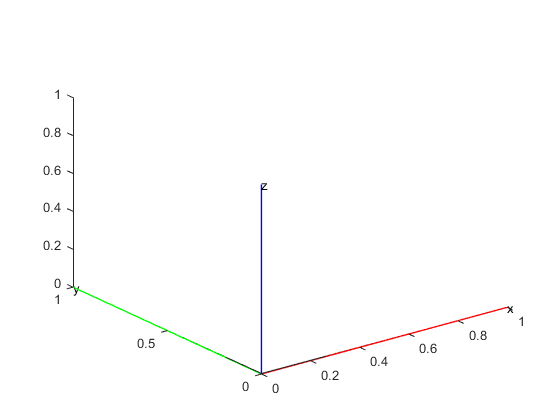

plot(r1);

#### Sequential rotations

Sequential rotations are obtained by post-multiplication. For example, the transformation between the neutral reference frame by $\bf{r}_1$ followed by $\bf{r}_2$  is 


$${\mathit{\mathbf{r}}}_3 ={\mathit{\mathbf{r}}}_1 {\mathit{\mathbf{r}}}_2$$


For example

clear all;
include_namespace_dq
disp('Displaying the result of the sequential multiplication r1*r2*r3')

Displaying the result of the sequential multiplication r1*r2*r3


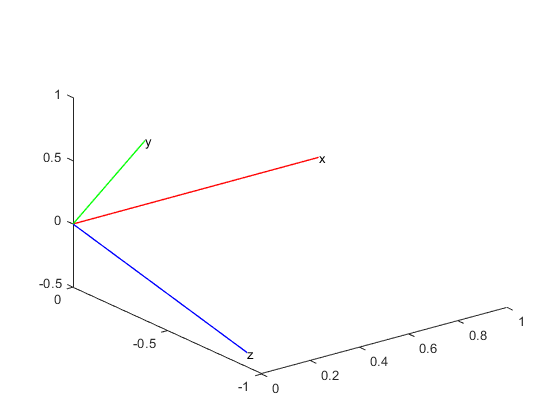

r1 = cos(pi/16) + i_*sin(pi/16);
r2 = cos(pi/4) + i_*sin(pi/4);
r3 = r1*r2;
plot(r3);

We can also plot all intermediary rotations using subplot.

clear all;
include_namespace_dq
disp('Displaying the result of the sequential multiplication using subplot')

Displaying the result of the sequential multiplication using subplot


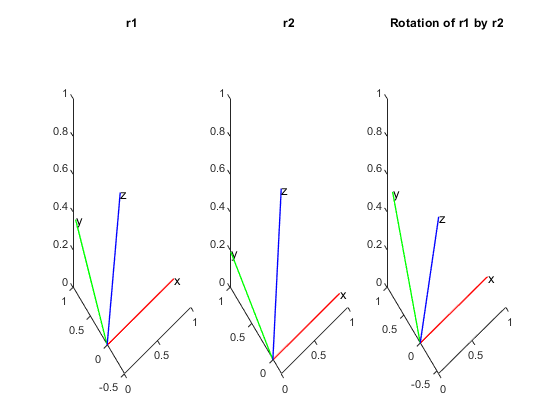

r1 = cos(pi/16) + i_*sin(pi/16);
r2 = cos(pi/32) + i_*sin(pi/32);
r3 = r1*r2;

subplot(1,3,1);
plot(r1);
title('r1');
subplot(1,3,2);
plot(r2);
title('r2');
subplot(1,3,3);
plot(r3);
title('Rotation of r1 by r2');

#### Reverse rotation

The reverse rotation can be obtained using the conjugate operation, because the unit quaternion have unit norm. Hence, 


$$r_1 {\left(r_1 \right)}^* =1$$


# Homework

Note: Dont forget to add

include_namespace_dq

in the beginning of your script.

- Create a MATLAB script called [quaternion_basics_homework.m]. On it, do the following tasks.

- Store, in $r_1$, the value of a rotation of $\phi =\frac{\pi \;\;}{8}\;\textrm{rad}$ about the x-axis.

- Store, in $r_2$, the value of a rotation of $\phi =\frac{\pi \;\;}{16}\;\textrm{rad}$ about the y-axis.

- Store, in $r_3$, the value of a rotation of $\phi =\frac{\pi \;\;}{32}\;\textrm{rad}$ about the z-axis.

- Calculate the result of the sequential rotation of the neutral reference-frame by $r_1$, followed by $r_2$, followed by $r_3$, and store it in ${\mathit{\mathbf{r}}}_4$. Plot ${\mathit{\mathbf{r}}}_4$.

- Find the reverse rotation of ${\mathit{\mathbf{r}}}_4$ and store it in ${\mathit{\mathbf{r}}}_5$.

- Rotate ${\mathit{\mathbf{r}}}_5$ by ${360}^{\circ \;}$ about the x-axis and store it in ${\mathit{\mathbf{r}}}_6$. Is ${\mathit{\mathbf{r}}}_5 =-{\mathit{\mathbf{r}}}_6$? Plot ${\mathit{\mathbf{r}}}_5$ and ${\mathit{\mathbf{r}}}_6$ to confirm that they represent the same rotation.

# Bonus Homework

- What is the general form of the quaternion multiplication? Multiply ${\mathit{\mathbf{h}}}_1 =a_1 +b_1 \hat{\;\i \;} +c_1 \hat{\;\j \;} +d_1 \hat{\;k}$ and ${\mathit{\mathbf{h}}}_2 =a_2 +b_2 \hat{\;\i \;} +c_2 \hat{\;\j \;} +d_2 \hat{\;k}$ on pen and paper and find ${\mathit{\mathbf{h}}}_3 =a_3 +b_3 \hat{\;\i \;} +c_3 \hat{\;\j \;} +d_3 \hat{\;k}$.

- What is the general form of the quaternion norm? Simplify $\sqrt{\;{\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_1^* }$ on pen and paper.

- Show that every unit quaternion, written as $\mathit{\mathbf{r}}=\cos \left(\frac{\phi }{2}\right)+\textrm{vsin}\left(\frac{\;\phi \;}{2}\right)$, has unit norm. Do that on pen and paper.